clear
load hall
P = double(hall_gray(1:120,1:120))-128;
[N,~] = size(P);

% 生成D
D = zeros(N);
for j = 1:N
    D(1,j)=1/sqrt(2);
end
for i = 2:N
    for j = 1:N
        D(i,j)=cos(pi*(i-1)*(2*j-1)/(2*N));
    end
end
D = D*sqrt(2/N)

D =     0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913    0.0913
    0.1291    0.1290    0.1288    0.1286    0.1282    0.1278    0.1272    0.1266    0.1259    0.1251    0.1243    0.1233    0.1222    0.1211    0.1199    0.1186    0.1172    0.1158    0.1143    0.1126    0.1109    0.1092    0.1073    0.1054    0.1034    0.1014    0.0993    0.0971    0.0948    0.0925    0.0901    0.0876    0.0851    0.0826    0.0799    0.0772    0.0745    0.0717    0.0689    0.0660    0.0631    0.0601    0.0571    0.0540    0.0510    0.0478    0.0447    0.0415    0.0383    0

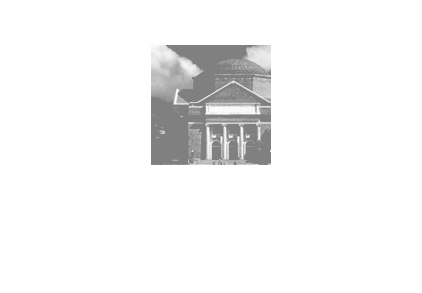


% 做变换
C = D*P*ctranspose(D);

% 变0操作
C1 = C;
C1(:,N-4:N)=0;
C2 = C;
C2(:,1:4)=0;

% 做逆变换
Q = uint8(ctranspose(D)*C*D)+128;
Q1 = uint8(ctranspose(D)*C1*D)+128;
Q2 = uint8(ctranspose(D)*C2*D)+128;

imshow(Q);

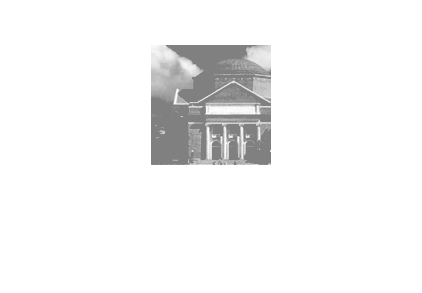

imshow(Q1);

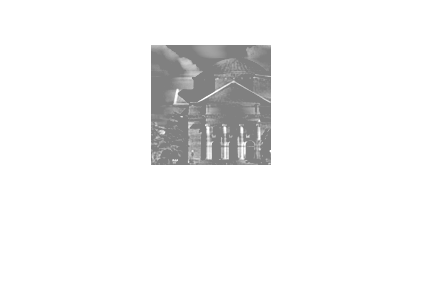

imshow(Q2);